%=========================================================================
% Lecture 16: In Class Tutorial
%
% This function calculates the radial equilibrium function for an axially 
% stretched and pressurized thick wall vessel and is part of the set of 
% equations you will implement for your vasculature project
%
% Input data: 
%   luminal pressure (Pi), axial stretch (lambdaz_v) 
%   material parameters, radii in ktf (Ri, Ro)
%
% Output data:
%   approximation of the outer radius, ro
%
% The inverse solution of the radial equilibrium involves finding
% the root of the equation:
%   Pi - int_{ri}^{ro} (tqq-trr)/r dr = 0
%=========================================================================

% Clean environemnts
close all, clear all, clc

Load and Define INPUT DATA


% Control refers to a age-matched healthy model
control_data = load("Input_HypertensionControl_ATA.mat");
test_data = load("Input_Hypertension_ATA.mat");

% Obtains material parameters
material_control = control_data.estimated_parameters;
material_test = test_data.estimated_parameters;

% Loads control parameters
control_lambdaz_exp = control_data.data_kl.lambdaz_exp;
control_Psys_exp = control_data.data_kl.Psys_exp;
control_ref_outer_radius = control_data.data_ktf.or_exp;
control_ref_inner_radius = control_data.data_ktf.ir_exp;
control_thickness = control_data.data_ktf.h_exp;

% Load test parameters (hypertensions)
test_lambdaz_exp = test_data.data_kl.lambdaz_exp;
test_Psys_exp = test_data.data_kl.Psys_exp;
test_ref_outer_radius = test_data.data_ktf.or_exp;
test_ref_inner_radius = test_data.data_ktf.ir_exp;
test_thickness = test_data.data_ktf.h_exp;

%% Solve the equilibrium equation
% Equilibrium equation for a pressurized and axially stretched vessel
% Unknown: outer radius, ro
% ro will be estimated as the roots of the equilibrium equation

H=cell(1,2);
H{1,1}=@equilibrium_r_or_loaded; %handle to equilibrium equation 
H{1,2}=@equilibrum_z_fz_loaded;

% Parameter to be estimated in loaded configuration is the outer radius (ro) 
% x0 is the initial guess for ro based on the input experimental data

       

        
% DELIVERABLE - Plot Luminal Pressure vs Outer Diameter

% All luminal presure to be tested
luminalP = 10:5:140;

% Stretches to be modeled
control_axialStretch = [control_lambdaz_exp, control_lambdaz_exp*1.05, control_lambdaz_exp*0.95];
test_axialStretch = [test_lambdaz_exp, test_lambdaz_exp*1.05, test_lambdaz_exp*0.95];

% Initialize radius result
control_or_est = zeros(3, length(luminalP));
test_or_est = zeros(3, length(luminalP));

% Initialize force results
control_fz_est = zeros(3, length(luminalP));
test_fz_est = zeros(3, length(luminalP));


% Loop through stretches
for stretch_index = 1:length(control_axialStretch)
    control_stretch = control_axialStretch(stretch_index)
    test_stretch = test_axialStretch(stretch_index)
    
    % Loop through pressures

    for P_index = 1:length(luminalP)

        % Current pressure being tested
        Pi = luminalP(P_index);
        Pi = Pi*0.133322 % From mmHg to kPa

        % GET R USING NEWTON RAPHSON% 

        % Control
        control_r = Newton_Raphson(H{1,1}, control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch, Pi, material_control, ...
            control_ref_outer_radius); 
        % Save results
        control_or_est(stretch_index, P_index) = control_r;

        % Test
        test_r = Newton_Raphson(H{1,1}, test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, Pi, material_test, ...
            test_ref_outer_radius); 
        % Save results
        test_or_est(stretch_index, P_index) = test_r;


        % GET CURRENT F WITH OPTIMIZED R

        % Control
        control_fz_est(stretch_index, P_index) = equilibrium_z_fz_loaded(control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch,material_control,control_r);

        % Test
        test_fz_est(stretch_index, P_index) = equilibrium_z_fz_loaded(test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, material_test,test_r);
        
        
    end

end

control_stretch = 1.9761

test_stretch = 1.4955

Pi = 1.3332

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-16

x = 0.6272

---
Maximum number of iterations reached
---


iter = 1000

f = -1.6431e-14

x = 0.9417

Pi = 1.9998

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-16

x = 0.6779

---
Maximum number of iterations reached
---


iter = 1000

f = -1.1990e-14

x = 0.9522

Pi = 2.6664

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.7501

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9650

Pi = 3.3331

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-16

x = 0.8349

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 0.9804

Pi = 3.9997

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 0.9095

---
Maximum number of iterations reached
---


iter = 1000

f = -1.3323e-15

x = 0.9976

Pi = 4.6663

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9670

---
Maximum number of iterations reached
---


iter = 1000

f = -1.7764e-15

x = 1.0159

Pi = 5.3329

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 1.0113

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.0339

Pi = 5.9995

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 1.0463

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.0510

Pi = 6.6661

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-16

x = 1.0748

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.0668

Pi = 7.3327

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0987

---
Maximum number of iterations reached
---


iter = 1000

f = -7.1054e-15

x = 1.0809

Pi = 7.9993

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 1.1191

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 1.0936

Pi = 8.6659

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.1368

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.1050

Pi = 9.3325

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.1524

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.1152

Pi = 9.9992

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1662

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-14

x = 1.1244

Pi = 10.6658

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1787

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.1327

Pi = 11.3324

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1900

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.1403

Pi = 11.9990

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.2003

---
Maximum number of iterations reached
---


iter = 1000

f = 2.3093e-14

x = 1.1472

Pi = 12.6656

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.2097

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1535

Pi = 13.3322

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-15

x = 1.2185

---
Maximum number of iterations reached
---


iter = 1000

f = -1.7764e-15

x = 1.1593

Pi = 13.9988

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.2265

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5987e-14

x = 1.1647

Pi = 14.6654

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5987e-14

x = 1.2341

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-14

x = 1.1697

Pi = 15.3320

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2411

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1744

Pi = 15.9986

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.2477

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0658e-14

x = 1.1787

Pi = 16.6653

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2540

---
Maximum number of iterations reached
---


iter = 1000

f = 3.1974e-14

x = 1.1828

Pi = 17.3319

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.2598

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-14

x = 1.1866

Pi = 17.9985

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.2654

---
Maximum number of iterations reached
---


iter = 1000

f = 3.1974e-14

x = 1.1903

Pi = 18.6651

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.2706

---
Maximum number of iterations reached
---


iter = 1000

f = 4.6185e-14

x = 1.1937

control_stretch = 2.0749

test_stretch = 1.5703

Pi = 1.3332

---
Maximum number of iterations reached
---


iter = 1000

f = 2.4425e-15

x = 0.6145

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 0.9401

Pi = 1.9998

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-16

x = 0.6577

---
Maximum number of iterations reached
---


iter = 1000

f = -1.8874e-14

x = 0.9474

Pi = 2.6664

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-16

x = 0.7177

---
Maximum number of iterations reached
---


iter = 1000

f = 2.2204e-15

x = 0.9558

Pi = 3.3331

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-16

x = 0.7924

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-16

x = 0.9654

Pi = 3.9997

---
Maximum number of iterations reached
---


iter = 1000

f = 1.3323e-15

x = 0.8661

---
Maximum number of iterations reached
---


iter = 1000

f = 1.3323e-15

x = 0.9763

Pi = 4.6663

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9267

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 0.9885

Pi = 5.3329

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9743

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 1.0018

Pi = 5.9995

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 1.0121

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.0157

Pi = 6.6661

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0428

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.0299

Pi = 7.3327

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0685

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.0438

Pi = 7.9993

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.0904

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.0571

Pi = 8.6659

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0658e-14

x = 1.1093

---
Maximum number of iterations reached
---


iter = 1000

f = -1.0658e-14

x = 1.0695

Pi = 9.3325

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1259

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.0810

Pi = 9.9992

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1406

---
Maximum number of iterations reached
---


iter = 1000

f = -1.2434e-14

x = 1.0915

Pi = 10.6658

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1539

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2434e-14

x = 1.1011

Pi = 11.3324

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1658

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.1099

Pi = 11.9990

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1767

---
Maximum number of iterations reached
---


iter = 1000

f = 1.9540e-14

x = 1.1179

Pi = 12.6656

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.1867

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-14

x = 1.1253

Pi = 13.3322

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1959

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.1321

Pi = 13.9988

---
Maximum number of iterations reached
---


iter = 1000

f = -7.1054e-15

x = 1.2044

---
Maximum number of iterations reached
---


iter = 1000

f = 2.1316e-14

x = 1.1383

Pi = 14.6654

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.2123

---
Maximum number of iterations reached
---


iter = 1000

f = 3.0198e-14

x = 1.1441

Pi = 15.3320

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2197

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1495

Pi = 15.9986

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-15

x = 1.2267

---
Maximum number of iterations reached
---


iter = 1000

f = 2.1316e-14

x = 1.1545

Pi = 16.6653

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.2332

---
Maximum number of iterations reached
---


iter = 1000

f = 2.4869e-14

x = 1.1592

Pi = 17.3319

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.2393

---
Maximum number of iterations reached
---


iter = 1000

f = 3.9080e-14

x = 1.1636

Pi = 17.9985

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.2452

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1678

Pi = 18.6651

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2507

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1717

control_stretch = 1.8773

test_stretch = 1.4207

Pi = 1.3332

---
Maximum number of iterations reached
---


iter = 1000

f = -2.2204e-16

x = 0.6396

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 0.9510

Pi = 1.9998

---
Maximum number of iterations reached
---


iter = 1000

f = -2.2204e-16

x = 0.6965

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9644

Pi = 2.6664

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 0.7784

---
Maximum number of iterations reached
---


iter = 1000

f = -1.3323e-15

x = 0.9814

Pi = 3.3331

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-16

x = 0.8683

---
Maximum number of iterations reached
---


iter = 1000

f = -2.2204e-15

x = 1.0009

Pi = 3.9997

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-16

x = 0.9416

---
Maximum number of iterations reached
---


iter = 1000

f = -4.8850e-15

x = 1.0211

Pi = 4.6663

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 0.9963

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-15

x = 1.0405

Pi = 5.3329

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0381

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.0583

Pi = 5.9995

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 1.0712

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0743

Pi = 6.6661

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-16

x = 1.0983

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.0884

Pi = 7.3327

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 1.1210

---
Maximum number of iterations reached
---


iter = 1000

f = 9.7700e-15

x = 1.1010

Pi = 7.9993

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 1.1404

---
Maximum number of iterations reached
---


iter = 1000

f = 1.3323e-14

x = 1.1122

Pi = 8.6659

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.1573

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.1222

Pi = 9.3325

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.1722

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2434e-14

x = 1.1312

Pi = 9.9992

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.1855

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1394

Pi = 10.6658

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1974

---
Maximum number of iterations reached
---


iter = 1000

f = -1.7764e-15

x = 1.1468

Pi = 11.3324

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.2083

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.1535

Pi = 11.9990

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.2182

---
Maximum number of iterations reached
---


iter = 1000

f = 3.0198e-14

x = 1.1597

Pi = 12.6656

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.2273

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1654

Pi = 13.3322

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0658e-14

x = 1.2357

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.1707

Pi = 13.9988

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.2435

---
Maximum number of iterations reached
---


iter = 1000

f = 4.0856e-14

x = 1.1756

Pi = 14.6654

---
Maximum number of iterations reached
---


iter = 1000

f = 1.9540e-14

x = 1.2508

---
Maximum number of iterations reached
---


iter = 1000

f = 2.3093e-14

x = 1.1802

Pi = 15.3320

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2434e-14

x = 1.2576

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1845

Pi = 15.9986

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2639

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.1885

Pi = 16.6653

---
Maximum number of iterations reached
---


iter = 1000

f = 2.1316e-14

x = 1.2700

---
Maximum number of iterations reached
---


iter = 1000

f = 4.2633e-14

x = 1.1923

Pi = 17.3319

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0658e-14

x = 1.2756

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1959

Pi = 17.9985

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.2810

---
Maximum number of iterations reached
---


iter = 1000

f = 4.2633e-14

x = 1.1993

Pi = 18.6651

---
Maximum number of iterations reached
---


iter = 1000

f = 2.1316e-14

x = 1.2861

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.2025

% Find diameter
control_diam = control_or_est .* 2

control_diam =     1.2543    1.3558    1.5002    1.6697    1.8190    1.9341    2.0225    2.0925    2.1496    2.1974    2.2382    2.2736    2.3047    2.3324    2.3574    2.3799    2.4005    2.4195    2.4369    2.4531    2.4682    2.4823    2.4955    2.5079    2.5197    2.5308    2.5413
    1.2291    1.3154    1.4354    1.5849    1.7322    1.8534    1.9485    2.0241    2.0857    2.1370    2.1808    2.2186    2.2518    2.2813    2.3077    2.3316    2.3534    2.3734    2.3918    2.4088    2.4247    2.4395    2.4534    2.4664    2.4787    2.4903    2.5013
    1.2791    1.3931    1.5567    1.7366    1.8831    1.9927    2.0763    2.1425    2.1966    2.2420    2.2808    2.3146    2.3444    2.3710    2.3949    2.4166    2.4364    2.4546    2.4714    2.4870    2.5015    2.5151    2.5279    2.5399    2.5513    2.5620    2.5722


test_diam = test_or_est .* 2

test_diam =     1.8834    1.9043    1.9301    1.9607    1.9953    2.0317    2.0679    2.1021    2.1335    2.1619    2.1873    2.2101    2.2305    2.2488    2.2654    2.2805    2.2943    2.3070    2.3186    2.3294    2.3394    2.3487    2.3574    2.3656    2.3733    2.3805    2.3874
    1.8803    1.8948    1.9116    1.9308    1.9527    1.9770    2.0035    2.0314    2.0598    2.0876    2.1141    2.1390    2.1619    2.1830    2.2022    2.2198    2.2358    2.2506    2.2641    2.2767    2.2883    2.2990    2.3091    2.3185    2.3273    2.3355    2.3433
    1.9019    1.9288    1.9627    2.0018    2.0423    2.0811    2.1167    2.1485    2.1769    2.2021    2.2245    2.2445    2.2625    2.2787    2.2935    2.3070    2.3194    2.3308    2.3414    2.3513    2.3604    2.3690    2.3771    2.3846    2.3918    2.3986    2.4050


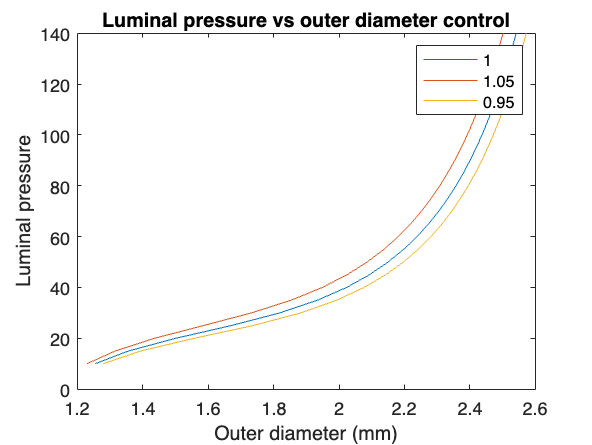


% Plot
figure()
plot(control_diam(1,:),luminalP, control_diam(2,:),luminalP, control_diam(3,:),luminalP)
xlabel("Outer diameter (mm)")
ylabel("Luminal pressure")
legend("1", "1.05", "0.95")
title("Luminal pressure vs outer diameter control")

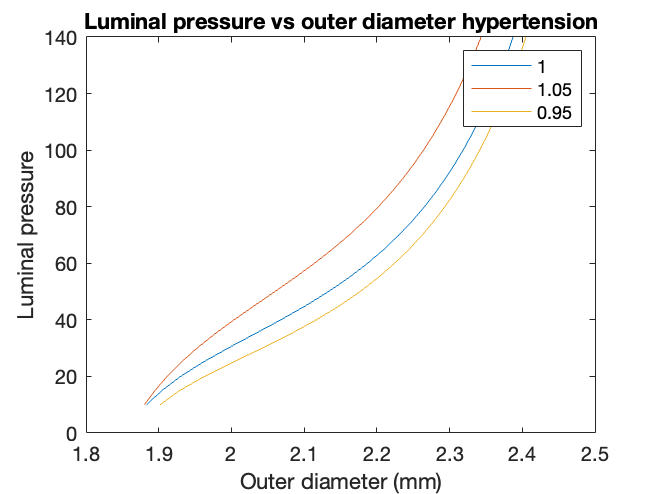


% Plot
figure()
plot(test_diam(1,:),luminalP, test_diam(2,:),luminalP, test_diam(3,:),luminalP)
xlabel("Outer diameter (mm)")
ylabel("Luminal pressure")
legend("1", "1.05", "0.95")
title("Luminal pressure vs outer diameter hypertension")

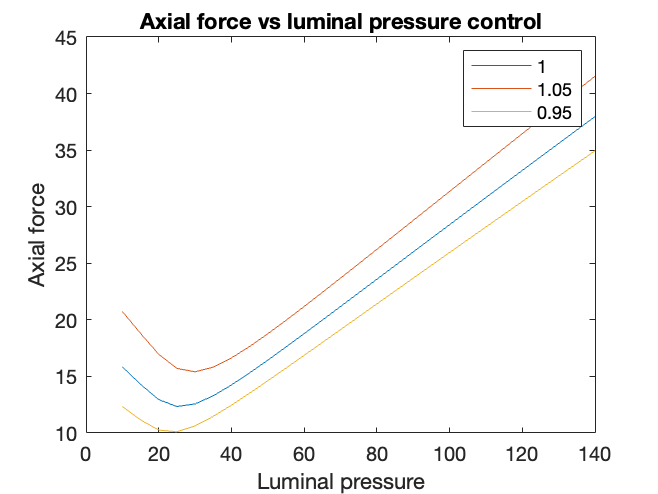


% Plot
figure()
plot(luminalP, control_fz_est(1,:),luminalP, control_fz_est(2,:),luminalP, control_fz_est(3,:))
xlabel("Luminal pressure")
ylabel("Axial force")
legend("1", "1.05", "0.95")
title("Axial force vs luminal pressure control")

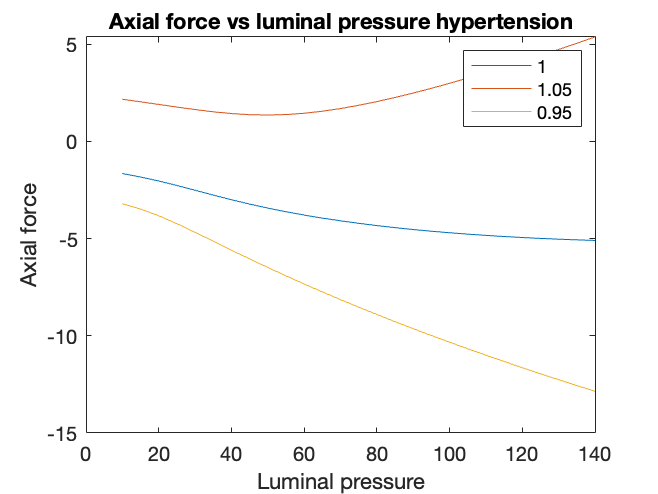


% Plot
figure()
plot(luminalP, test_fz_est(1,:),luminalP, test_fz_est(2,:),luminalP, test_fz_est(3,:))
xlabel("Luminal pressure")
ylabel("Axial force")
legend("1", "1.05", "0.95")
title("Axial force vs luminal pressure hypertension")